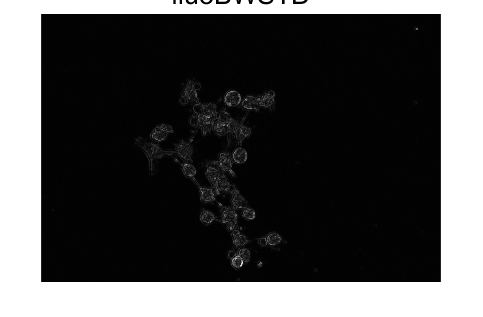

% 读入需要处理的图像
fluoGray = rgb2gray(imread('003-bf.jpg'));

% 第一步: 滤波
nHood = true(13);
fluoSTD = stdfilt(fluoGray,nHood);
fluoSTD = rescale(fluoSTD);

imshow(fluoSTD)
title('fluoBWSTD','FontSize',16)

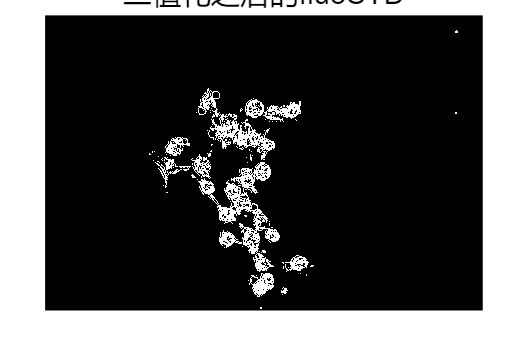


% 第二步： 二值化
fluoBW = imbinarize(fluoSTD);
imshow(fluoBW);
title('二值化之后的fluoSTD','FontSize',16)

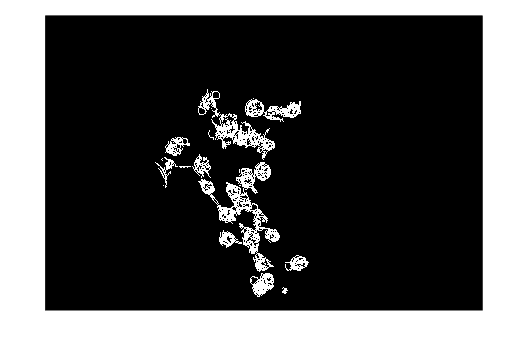


fluoBW = bwareaopen(fluoBW,2500); % 移除面积小于2500的
imshow(fluoBW);

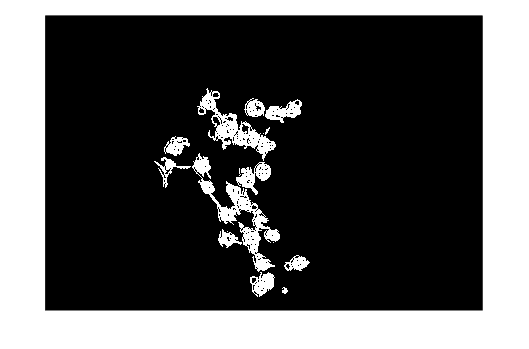


% Try : Growing Segmentations with Active Contours
% -1 1 越接近 1 背景越强
fluoBW = activecontour(fluoGray,fluoBW,20,...
    "Chan-Vese","ContractionBias",0.01,...
   "SmoothFactor",0.1);
imshow(fluoBW)

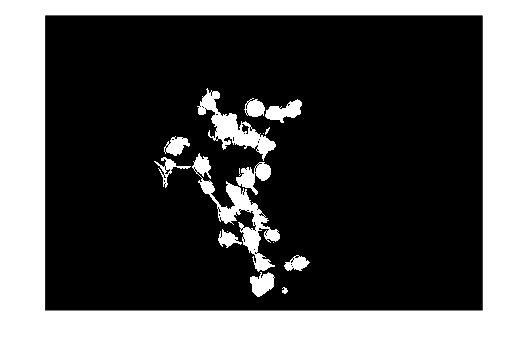

fluoBW = imfill(fluoBW,"holes"); % 填充
imshow(fluoBW);


rgbMask = BW2rgbMask(fluoBW)

rgbMask = 3648×5440×3 uint8 数组
rgbMask(:,:,1) =

  列 1 至 2,499

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

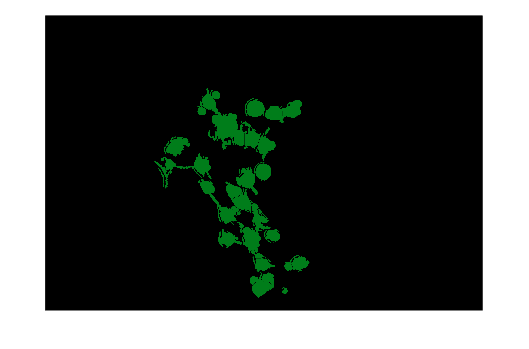

imshow(rgbMask)

% PSNR 计算
ref = imread('003-fluo.jpg'); % RGB 绿色图
imshow(ref);
PSNR = psnr(rgbMask,ref)

function rgbMask = BW2rgbMask(BW)
d = bwdist(~BW);
d = imcomplement(d);
d = imhmin(d,1);

% Calculate the watershed transform of d
fluoSep = watershed(d);
% imshow(fluoSep,[])

% Create RGB Mask
fluoSep(~BW) = 0;

% number_of_labels 
n = max(fluoSep(:));

a = 0.00;
b = 0.49;
c = 0.1;

map = [ones(n,1)*a ones(n,1)*b ones(n,1)*c];

rgbMask = label2rgb(fluoSep,map,'k');
end